clear

% Extract data from CSV files
[timestamps, cl_ramp_rpm, cl_ramp_ref, cl_ramp_u] = extractMotorData("DataSets/cl_zn_ramp10.csv");
[~, cl_step_rpm, cl_step_ref, cl_step_u ] = extractMotorData("DataSets/cl_zn_step.csv");
[~, cl_chirp_rpm, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/cl_zn_chrip8_1.csv");

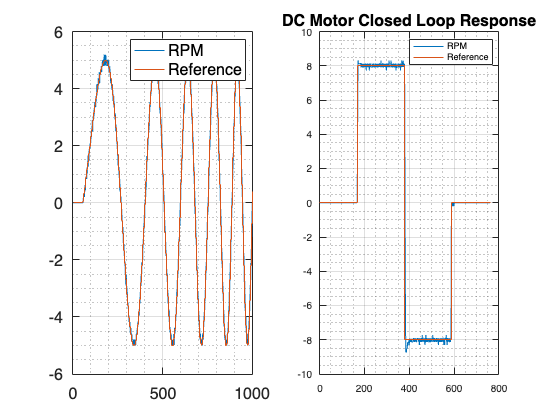

fig = figure;
subplot(1,2,1)
plot(cl_chirp_rpm(1:1001), 'LineWidth', 1); hold on; 
stairs(cl_chirp_ref(1:1001), 'LineWidth', 0.5); 
hold off; grid on; legend("RPM", "Reference", 'FontSize',14);
grid minor;
fontsize(16, "points");


subplot(1,2,2)
plot(cl_step_rpm,'LineWidth', 1); hold on;
stairs(cl_step_ref,'LineWidth', 1); grid on; grid minor; hold off
legend("RPM", "Reference"); 


title("DC Motor Closed Loop Response", 'FontSize',16);

% Extract data from CSV files
clear
[~, ramp_rpm, ramp_volt, ~] = extractMotorData("DataSets/ramp10_100.csv");
[~, sin1_1_rpm, sin1_volt, ~] = extractMotorData("DataSets/sin_1_1_100.csv");
[~, sin5_5_rpm, sin5_volt, ~] = extractMotorData("DataSets/sin_5_5_100.csv");
[~, sin1_8_rpm, sin1_8_volt, ~] = extractMotorData("DataSets/sin_1_8_100.csv");
[~, chirp_rpm, chirp_volt, ~] = extractMotorData("DataSets/chirp_1_10_100.csv");
[~, step_rpm, step_volt, ~] = extractMotorData("DataSets/openStep.csv");
[~, trig_rpm, trig_volt, ~] = extractMotorData("DataSets/openTrig.csv");

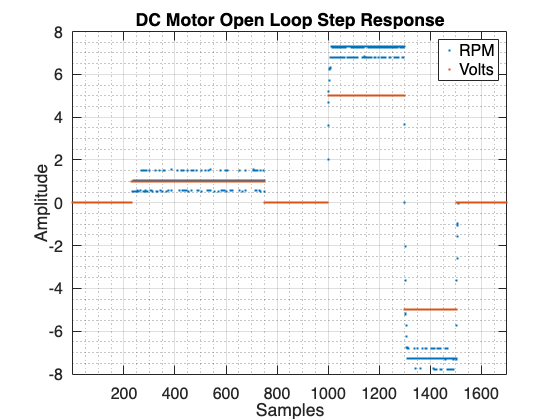

% Plot datasets
fig = figure;
plot(step_rpm(200:end), '.'); hold on; plot(step_volt(200:end), '.'); hold off; legend("RPM", "Volts"); grid on; grid minor;fontsize(16,"points");
title("DC Motor Open Loop Step Response"); xlabel("Samples"); ylabel("Amplitude"); xlim([1,1700]);

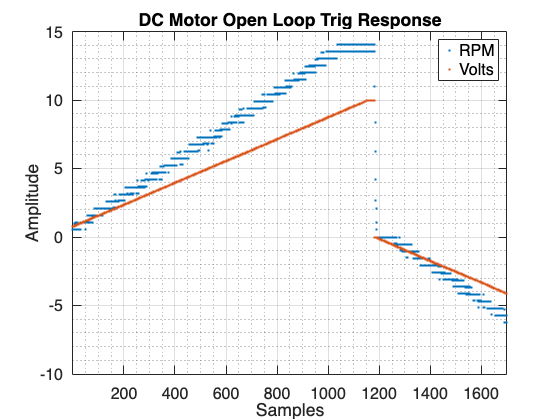

% Plot datasets
fig = figure;
plot(trig_rpm(200:end), '.'); hold on; plot(trig_volt(200:end), '.'); hold off; legend("RPM", "Volts"); grid on; grid minor;fontsize(16,"points");
title("DC Motor Open Loop Trig Response"); xlabel("Samples"); ylabel("Amplitude"); xlim([1,1700]);

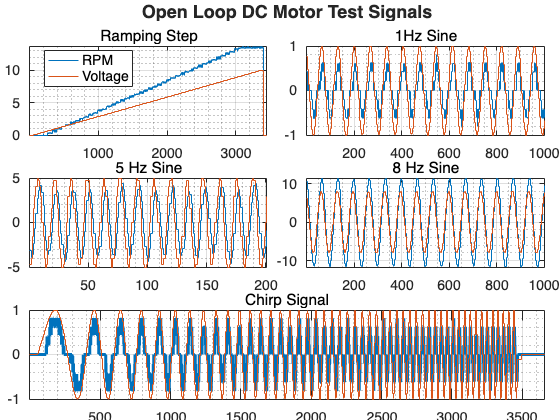

fig = figure;
fig.Color = 'w'; % White background
tlo = tiledlayout('flow', 'TileSpacing','tight', 'Padding','tight'); % Flexible tile layout

% Define consistent color theme
blue = [0, 0.4470, 0.7410];    % RGB for blue
red = [0.8500, 0.3250, 0.0980]; % RGB for red

% Open Loop Step Responses




% Main title settings
title(tlo, "Open Loop DC Motor Test Signals", ...
    'FontSize', 18, 'FontWeight', 'bold')


% Ramping Step Plot
ax1 = nexttile;
stairs(ramp_rpm, 'Color', blue, 'LineWidth', 1);
hold on;
stairs(ramp_volt, 'Color', red, 'LineWidth', 0.5);
hold off;
legend("RPM", "Voltage", 'FontSize', 14, 'Location', 'best');
grid on;grid minor;
subtitle("Ramping Step", 'FontSize', 16)
axis tight;

% 1Hz Sine Plot
ax2 = nexttile;
stairs(sin1_1_rpm(201:1201), 'Color', blue, 'LineWidth', 1);
hold on;
stairs(sin1_volt(201:1201), 'Color', red, 'LineWidth', 0.5);
hold off;
grid on;grid minor;
subtitle("1Hz Sine", 'FontSize', 16)
axis tight;

% 5Hz Sine Plot
ax3 = nexttile;
stairs(sin5_5_rpm(201:401), 'Color', blue, 'LineWidth', 1);
hold on;
stairs(sin5_volt(201:401), 'Color', red, 'LineWidth', 0.5);
hold off;
grid on;grid minor;
subtitle("5 Hz Sine", 'FontSize', 16)
axis tight;

% 8Hz Sine Plot
ax4 = nexttile;
stairs(sin1_8_rpm(201:1201), 'Color', blue, 'LineWidth', 1);
hold on;
stairs(sin1_8_volt(201:1201), 'Color', red, 'LineWidth', 0.5);
hold off;
grid on;grid minor;
subtitle("8 Hz Sine", 'FontSize', 16)
axis tight;

% Chirp Plot (Spanning two columns)
ax5 = nexttile([1,2]);
stairs(chirp_rpm, 'Color', blue, 'LineWidth', 3);
hold on;
stairs(chirp_volt, 'Color', red, 'LineWidth', 0.5);
hold off;
grid on; grid minor;
subtitle("Chirp Signal", 'FontSize', 16)
axis tight;

% Uniform font size for all axes
set([ax1, ax2, ax3, ax4, ax5], 'FontSize', 14)